close all
clear
clc

# Image filtering (2)

This demo shows how image filters can be used to enhance the image information content, which means for example improving the visibility of features of interest.

Different image filters are used for:  

- Image denoising

- Improving visibility of object edges 

## 2) Filters to enhance image details

This example demonstrates how to develop a wavelet-based filter to enhance interesting features in images.

Because wavelets expore features in your data at different scales, you can preserve relevant signal or image features while removing noise. In this example we will process mammography image portions showing microcalcifications: the objects to be preserved are microcalcifications (small bright spots), whereas the noise to be filtered out is the non-uniform image background (heterogeneous breast tissue). The steps are:

- Load images. 

- Decompose the image with a 2-D wavelet decomposition (with `wavedec2`) 

- Analyzed the high spatial frequency (HF) and low spatial frequency (LF) components at different scales

- Reconstruct the filtered image with a 2-D wavelet reconstruction (with `waverec2`)

- Show a filtered images where microcalcification are more clearly visible and the background is removed.

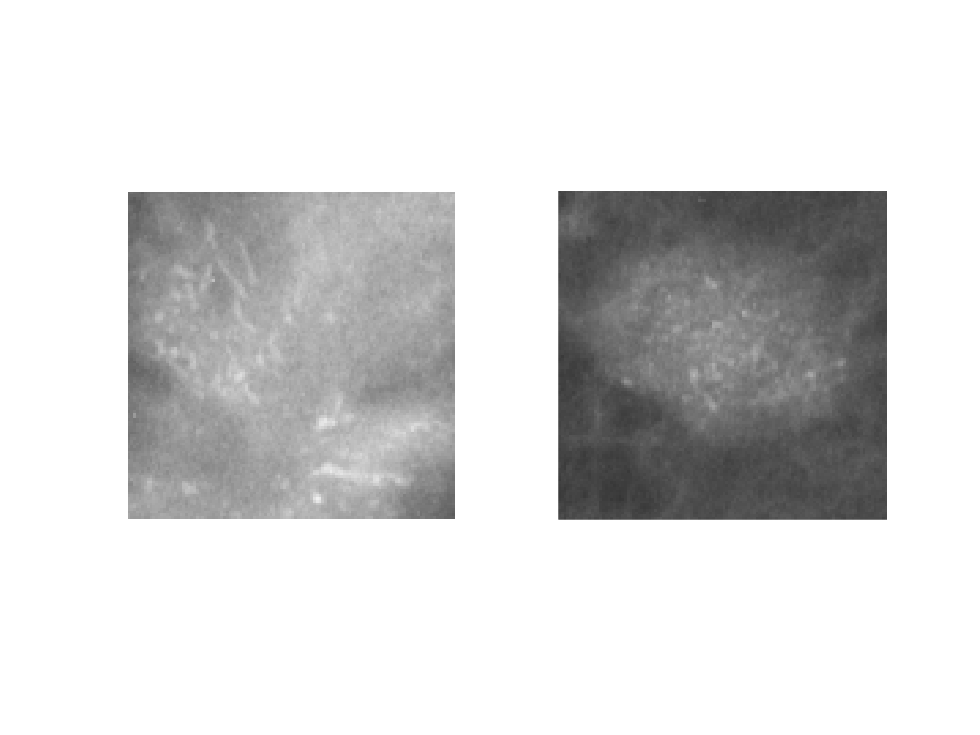

I1=imread('0006s1_1_1_1.pgm');
I2=imread('0039t1_2_1_1.pgm');
figure;
subplot(1,2,1), imshow(I1)

subplot(1,2,2), imshow(I2) 

To implement and visualize the wavelet decomposition on images you can launch the W`avelet Image Analyzer App `(within the `Image Processing and Computer Vision Apps`). The App allows you to interactly perform wavelet analysis, compare different choices of wavelets and levels of decomposition, select coefficients and store reconstructed images in the workspace. You cal also export your wavelet analysis as a MATLAB script.

Otherwise, you can directly code you analysis pipeline, by proceeding as follows, i.e. using the `wavedec2` and the `waverec2` functions.

Two-level wavelet decomposition with Daubechies wavelet

%wave='db1';  % you can try different wavelet (e.g. haar, sym, coif)
wave='sym3';
N=3;          % N = decomposition level
[c,s]=wavedec2(I1,N,wave);   

[C,S]=wavedec2(X,N,wavetype)

The matrix S (bookkeeping matrix) contains the dimensions of the wavelet coefficients by level and is used to parse the wavelet decomposition vector [C](https://it.mathworks.com/help/wavelet/ref/wavedec2.html?searchHighlight=wavedec2&s_tid=doc_srchtitle).

• S(1,:) = size of approximation coefficients(N).

• S(i,:) = size of detail coefficients (N-i+2) for i = 2, ...N+1 and S(N+2,:) = size(X) 

i.e.: S(2,:) = size of details at level L=(N-i+2)=3;

S(3,:) = size of details at level L=2

S(4,:) = size of details at level L=1

The vector of coefficient C contains first the unrolled approximation matrix, then the tree detail matrices (i.e. H, V, D) for the L=3,2,1 levels   

For example, for a 512-by-512 matrix:

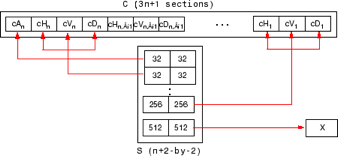

Extract and show the level 1 approximation and detail coefficients with `appcoef2` and `detcoef2`.

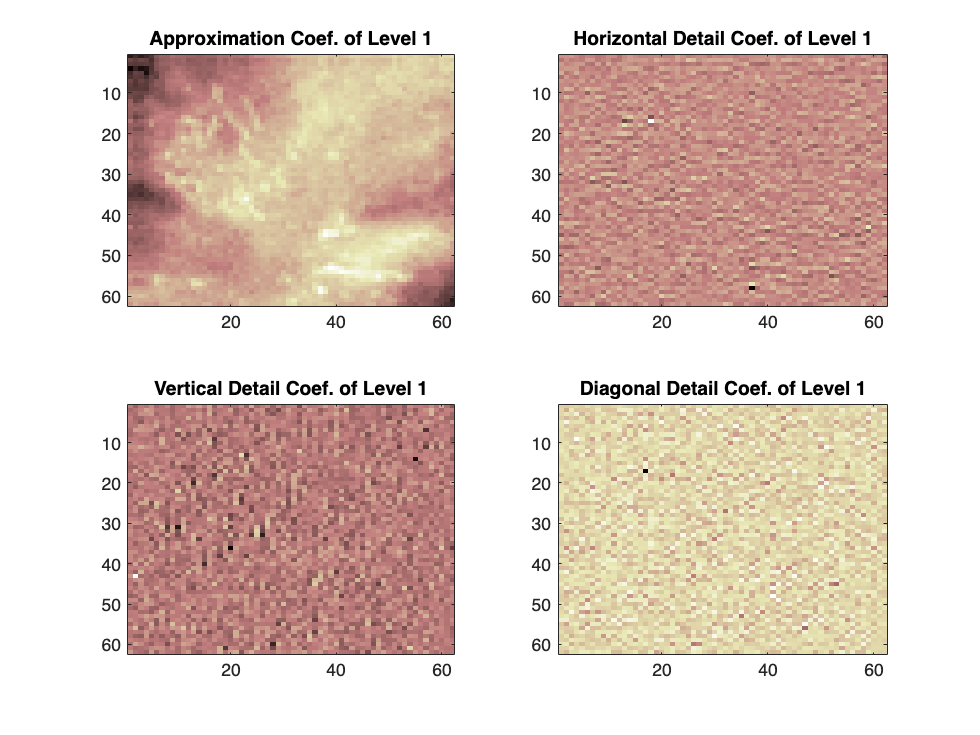

A1 = appcoef2(c,s,wave,1);
[H1,V1,D1] = detcoef2('all',c,s,1);

figure
subplot(2,2,1)
imagesc(A1)
colormap pink(255)
title('Approximation Coef. of Level 1')

subplot(2,2,2)
imagesc(H1)
title('Horizontal Detail Coef. of Level 1')

subplot(2,2,3)
imagesc(V1)
title('Vertical Detail Coef. of Level 1')

subplot(2,2,4)
imagesc(D1)
title('Diagonal Detail Coef. of Level 1')

Extract and show the level 2 approximation and detail coefficients.

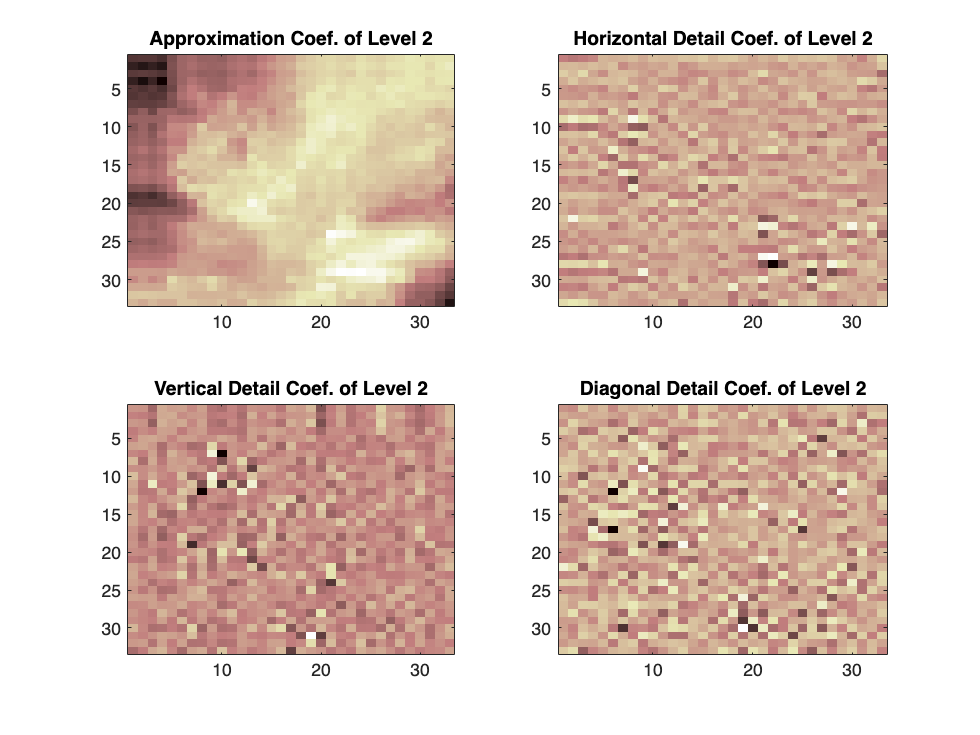

A2 = appcoef2(c,s,wave,2);
[H2,V2,D2] = detcoef2('all',c,s,2);

figure
subplot(2,2,1)
imagesc(A2)
colormap pink(255)
title('Approximation Coef. of Level 2')

subplot(2,2,2)
imagesc(H2)
title('Horizontal Detail Coef. of Level 2')

subplot(2,2,3)
imagesc(V2)
title('Vertical Detail Coef. of Level 2')

subplot(2,2,4)
imagesc(D2)
title('Diagonal Detail Coef. of Level 2')

Extract and show the level 3 approximation and detail coefficients.

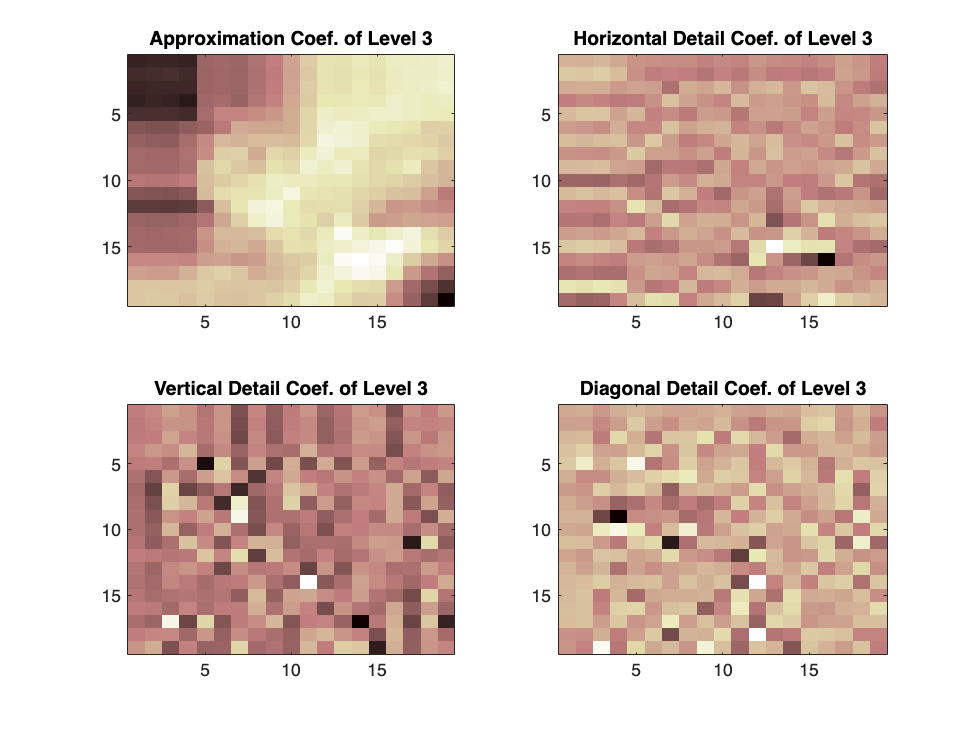

A3 = appcoef2(c,s,wave,3);
[H3,V3,D3] = detcoef2('all',c,s,3);

subplot(2,2,1)
imagesc(A3)
colormap pink(255)
title('Approximation Coef. of Level 3')

subplot(2,2,2)
imagesc(H3)
title('Horizontal Detail Coef. of Level 3')

subplot(2,2,3)
imagesc(V3)
title('Vertical Detail Coef. of Level 3')

subplot(2,2,4)
imagesc(D3)
title('Diagonal Detail Coef. of Level 3')

Manipulate the coefficients e.g. suppressing the approximation coefficient at level 3 (i.e. smoothed background intensity) and the detail coefficients at level 1 (noise).

Approximation and detail coefficients are stored in the c vector (check the size of `c`). It cointains the unrolled coefficient matrices, as follows: 

[A3(:); H3(:); V3(:); D3(:); H2(:); V2(:); D2(:); H1(:); V1(:); D1(:)].

We can create a vector of labels, where:

- First level detail coefficients (H1,V1,D1) are labelled as "1"

- Second level detail coefficients (H2,V2,D2) are labelled as "2"

- ....

- last level approximation as "0"

% We are working with decomposition on 3 levels (N=3)
size_CM=s(:,1).*s(:,2);   % same as prod(s,2)
c_labels= zeros(1,size_CM(1));
for il=1:N
    c_labels =  [c_labels (N+1-il)*ones(1,3*size_CM(il+1))];
end

Check that size(c) and size(c_labels) are the same. 

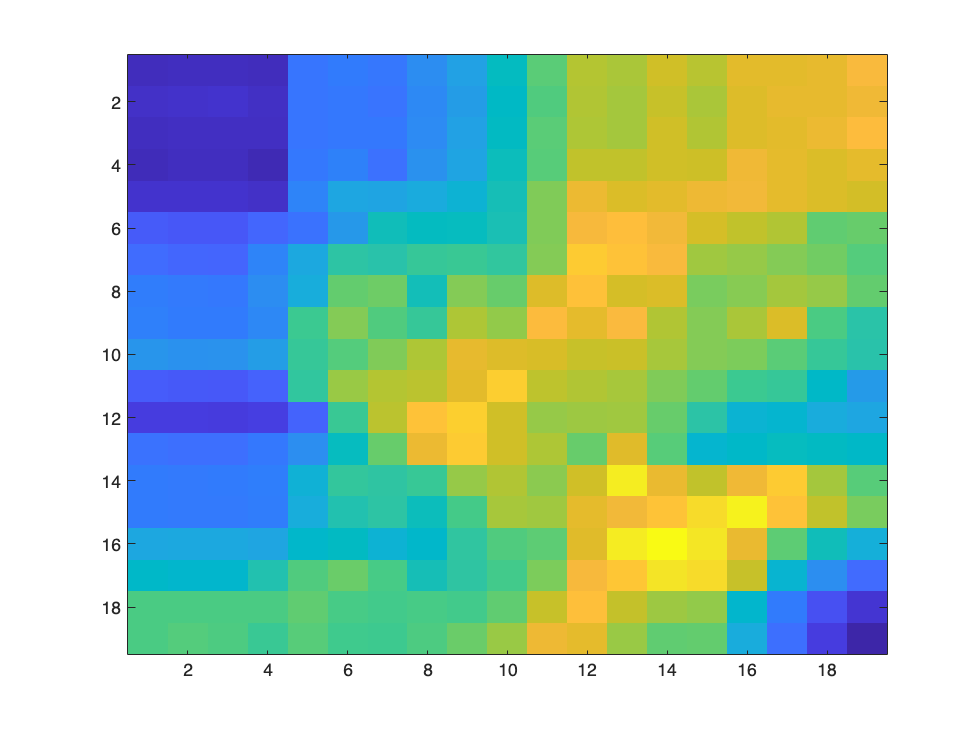

Approx_3=reshape(c(c_labels==0),[s(1,:)]);
figure;imagesc(Approx_3)

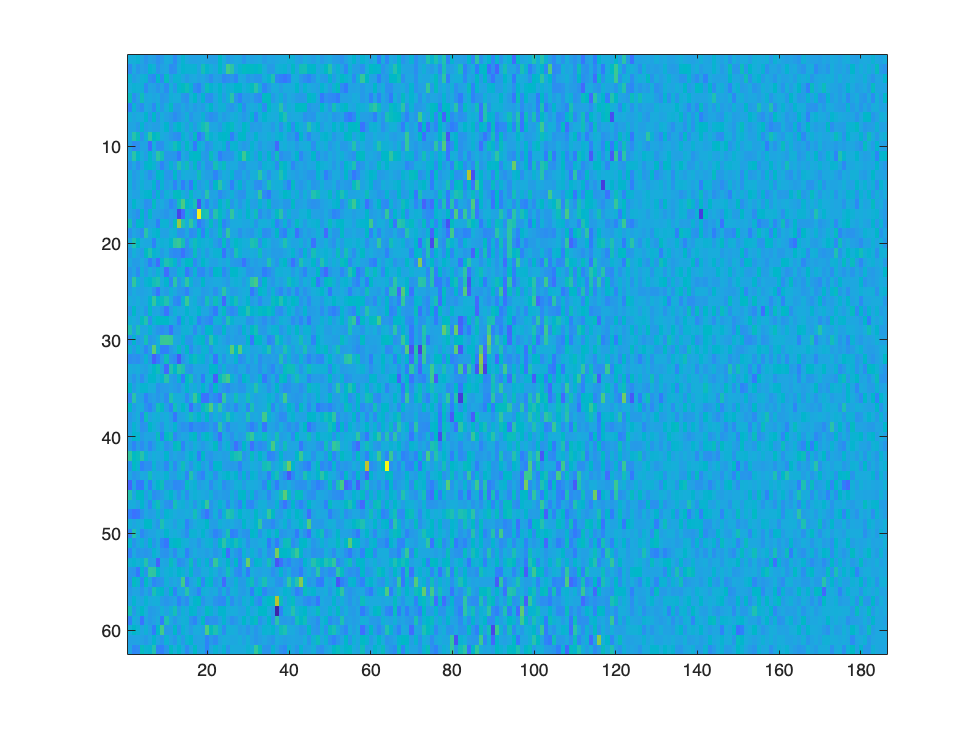

Details_1=reshape(c(c_labels==1),[s(4,1) 3*s(4,2)]);
figure;imagesc(Details_1)

Now that we have identified the coefficients, we can modify them.

We can figure out how to do it by looking first at their distributions

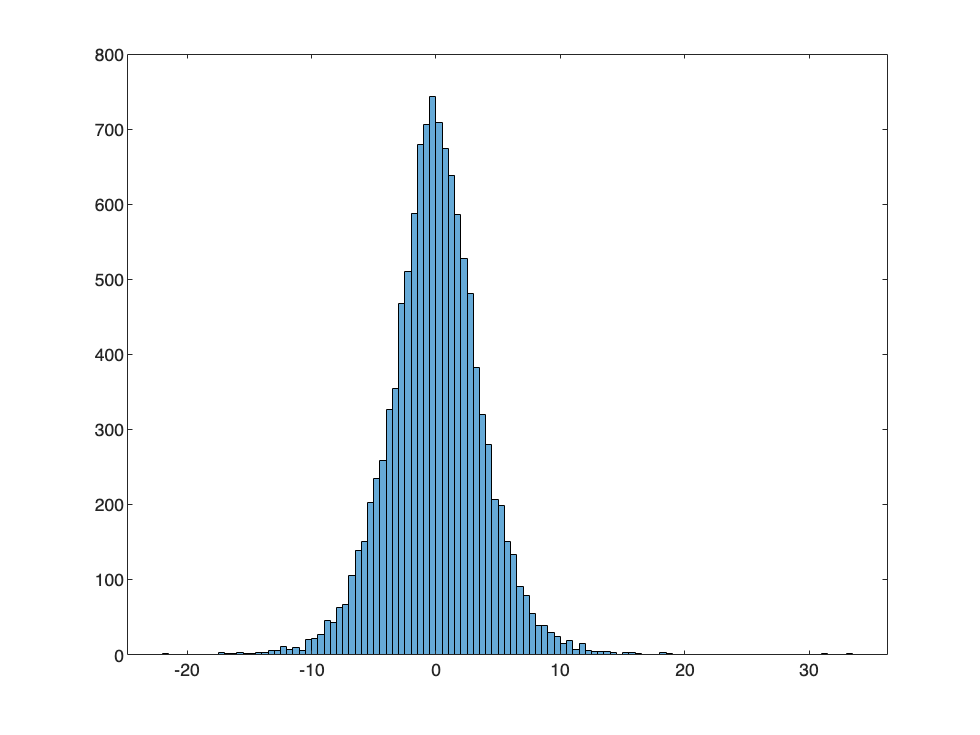

figure;histogram(c(c_labels==1))

std1=std(c(c_labels==1))

std1 = 3.6925

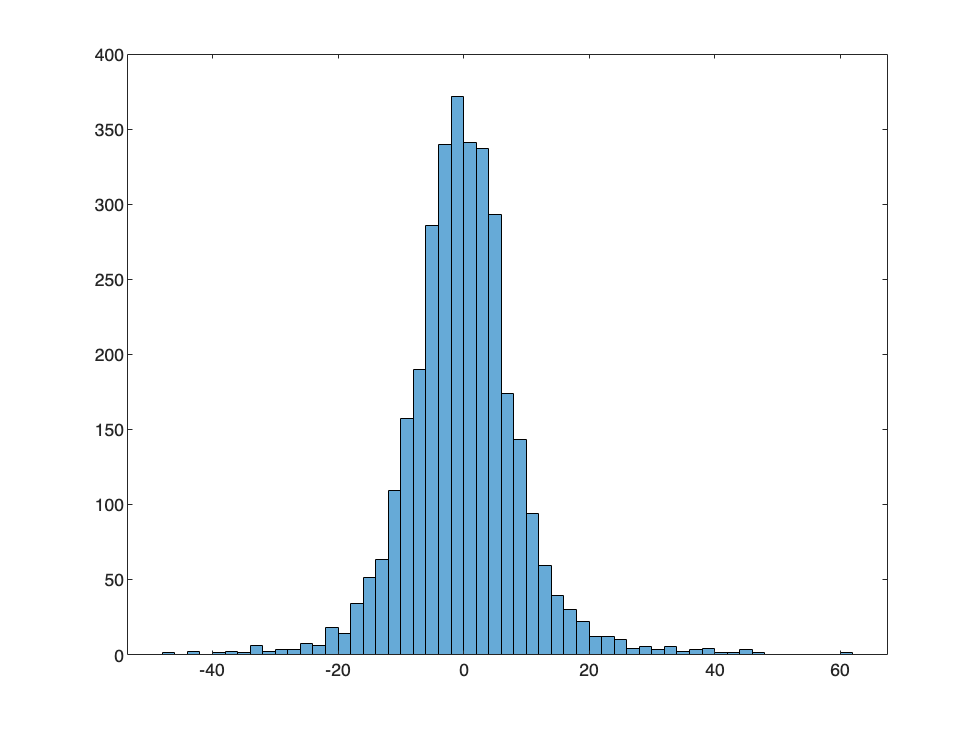

figure;histogram(c(c_labels==2))

std2=std(c(c_labels==2))

std2 = 8.9251

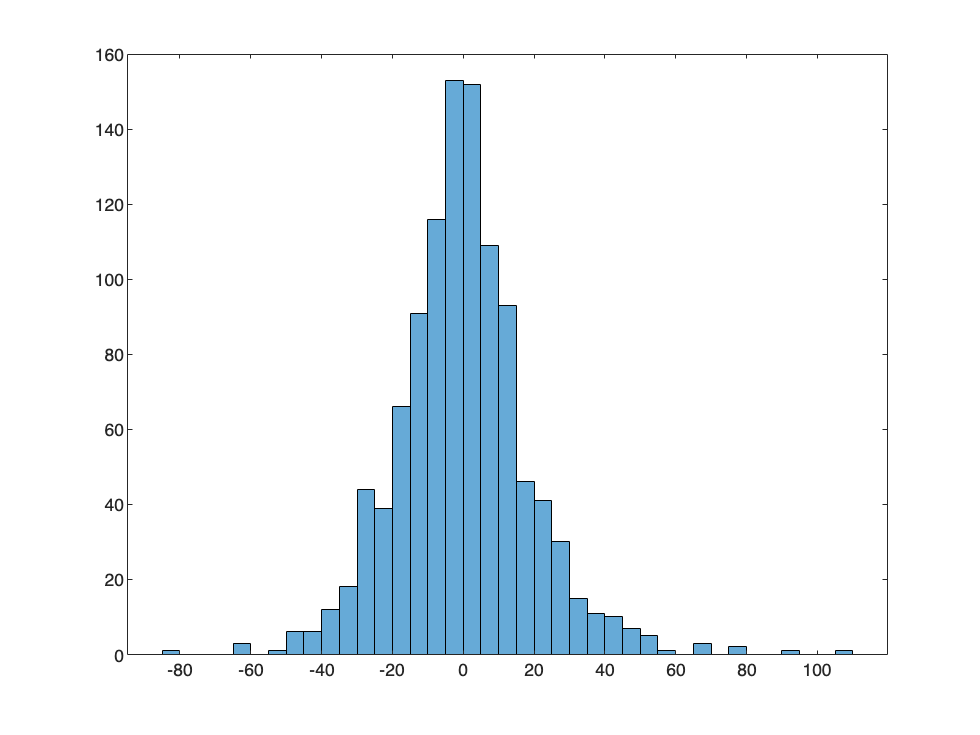

figure;histogram(c(c_labels==3))

std3=std(c(c_labels==3))

std3 = 18.7502

We can set thresholds of coefficients in terms of the standard deviations of their distributions and, for example set to zero the "low spatial frequency approximation" information, while keeping only the "high spatial frequency details" that exceed a certain number of standard deviations: 

c_mod=c;
c_mod(c_labels==0)=0;

c1=c(c_labels==1);
c2=c(c_labels==2);
c3=c(c_labels==3);
c1_mod=c1;
c1_mod(abs(c1)<std1)=0;
c2_mod=c2;
c2_mod(abs(c2)<std2)=0;
c3_mod=c3;
c3_mod(abs(c3)<std3)=0;

c_mod(c_labels==1)=c1_mod;
c_mod(c_labels==2)=c2_mod;
c_mod(c_labels==3)=c3_mod;


More compactly:

c_mod=c;
c_mod(c_labels==0)=0;
c_mod((c_labels==1)&(abs(c)<1*std1))=0;  % we can chose more stringent rules (e.g. 2*std1)
c_mod((c_labels==2)&(abs(c)<1*std2))=0;
c_mod((c_labels==3)&(abs(c)<1*std3))=0;


Once we have modified the coefficients we can reconstruct the image with `waverec2`

I1_Rec = waverec2(c_mod,s,wave);

display the reconstructed image alongside the original one:

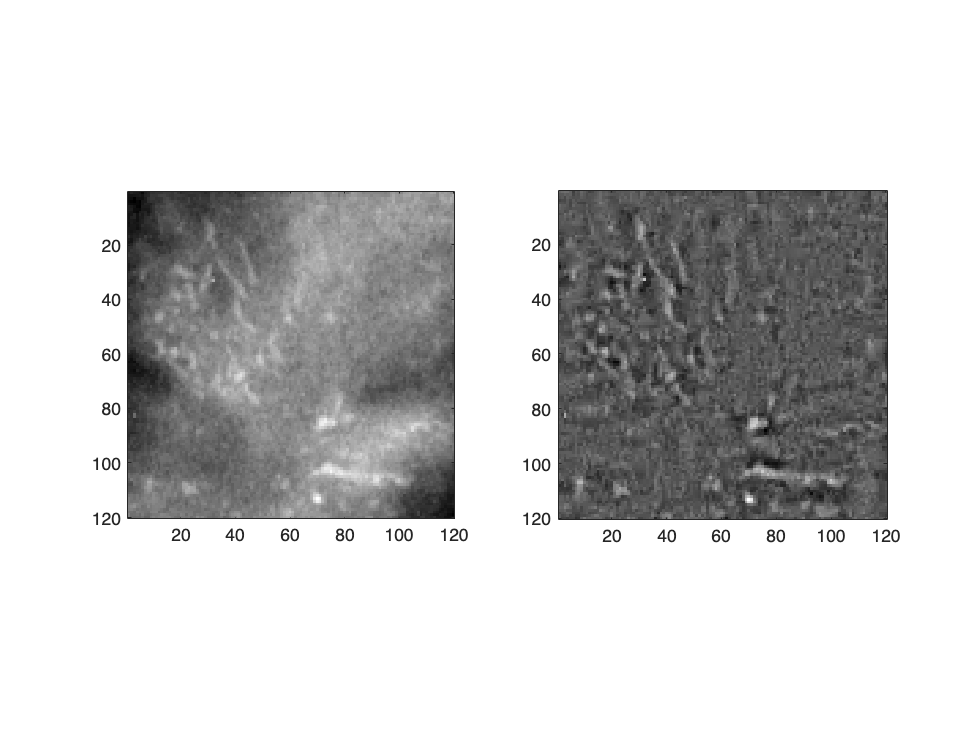

figure
subplot(1,2,1), imagesc(I1); axis square; colormap gray
subplot(1,2,2), imagesc(I1_Rec); axis square;  

We have now positive and negative walues, we can  keep only the positive values creating a mask (I1_Rec>0)

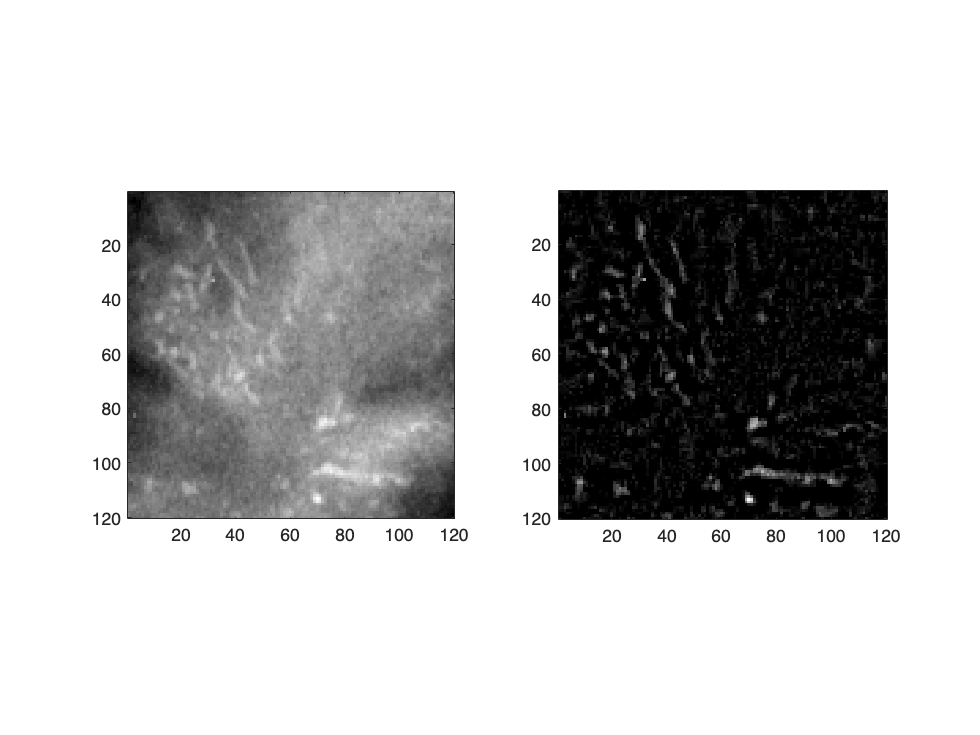

I1_Rec_masked=I1_Rec.*(I1_Rec>0);
figure
subplot(1,2,1), imagesc(I1); axis square; colormap gray
subplot(1,2,2), imagesc(I1_Rec_masked); axis square;  % 

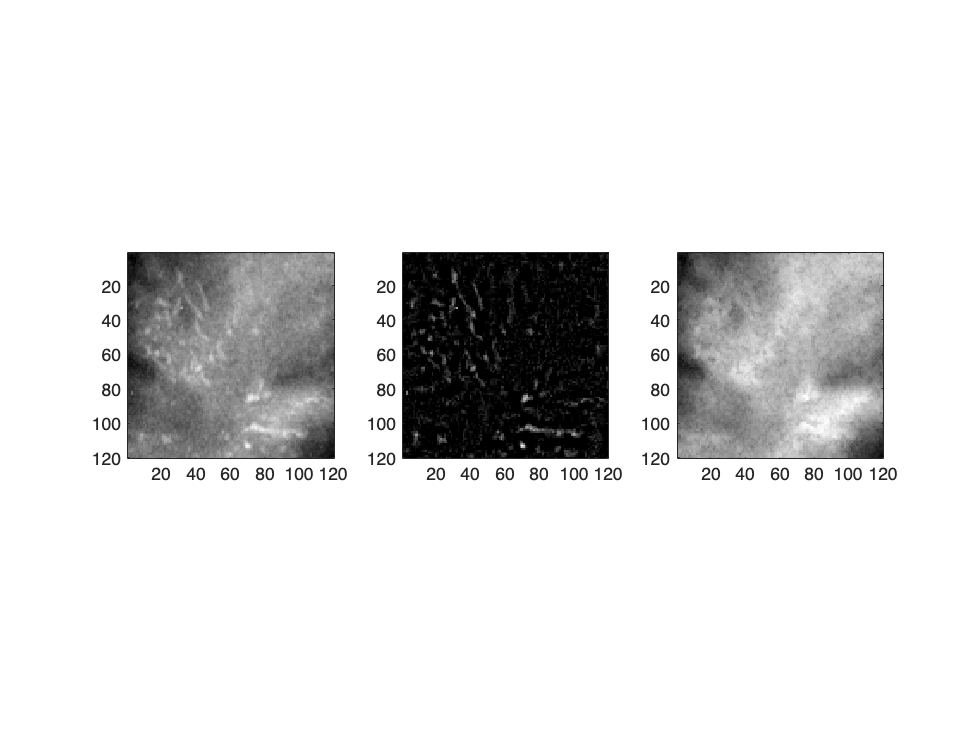

I1_remaining=double(I1)-I1_Rec_masked;
figure
subplot(1,3,1), imagesc(I1); axis square; colormap gray
subplot(1,3,2), imagesc(I1_Rec_masked); axis square;  % 
subplot(1,3,3), imagesc(I1_remaining); axis square;  % 

Repeat the demo with another image.

Try different manipulations of the coefficients, e.g.:

% try to keep only approximations at Level 3
% c_mod=c;
% c_mod(~c_labels==0)=0;
% microcalcifications disappear

% try to keep only details and set to zero approximations 
% c_mod=c;
% c_mod(c_labels==0)=0;
% microcalcifications are visible, but image is too noisy